clear all; close all; clc;

Using the following MATLAB code sample, complete the TODOs to calculate the range in meters of four targets with respective measured beat frequencies [0 MHz, 1.1 MHz, 13 MHz, 24 MHz].

You can use the following parameter values:

- The radar maximum range = 300m

- The range resolution = 1m

- The speed of light c = 3*10^8

Note : The sweep time can be computed based on the time needed for the signal to travel the maximum range. In general, for an FMCW radar system, the sweep time should be at least 5 to 6 times the round trip time. This example uses a factor of 5.5:

*** [https://www.siversima.com/wp-content/uploads/FMCW-Radar-App-Note.pdf](https://www.siversima.com/wp-content/uploads/FMCW-Radar-App-Note.pdf) ***

B_sweep  ( Sweep bandwidth) -> Difference between maximum and minimum frequency

T_s (Chirp time) -> time it takes from going to lower end of frequency to the higher end

f_b (Beat frequency) -> difference between transmitted and received frequency

t_d (time difference) -> difference between transmitted and received frequency TIME

R (Range) -> one way distance to object

c -> Speed of EM wave

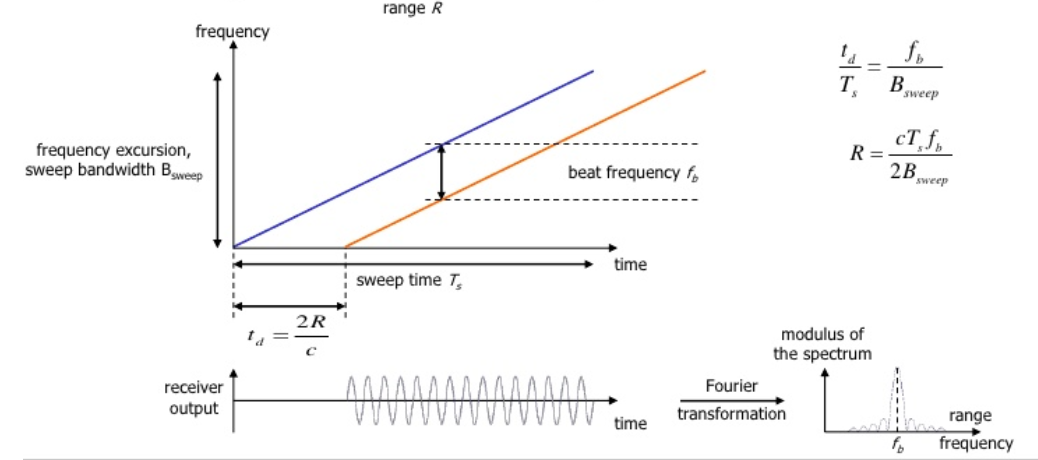

Based on the above information we can calculate the sat that

t_d/T_s = f_b/B_sweep ---------------------------------------------eq 1

We also know that

velocity = distance / time

And in our case velocity = velocity of light, distance = 2*R (two way -> | <-) and time = t_d

c = 2 * R / t_d

t_d = 2 * R /c ------------------------------------------------------------eq2

from eq1 and eq2

R = (c * T_s * f_b) / (2 * B_sweep)

% TODO : Find the Bsweep of chirp for 1 m resolution
c = 3*10^8;               % Speed of light
delta_r = 1;              % Range resolution 

B_sweep = c / 2 * delta_r; % Given formulae        
B_sweep_in_Mhz = B_sweep / 10^6

B_sweep_in_Mhz = 150

Sweep time should be grater than time required to cross the range of radar to avoid the interference in this case we will consider it 5.5 time

Range_max = 300;                     % Given

% TODO : Calculate the chirp time based on the Radar's Max Range
T_s = 5.5 * ((2 * Range_max) / c)

T_s = 1.1000e-05

% TODO : define the frequency shifts 
% Range = (c * T_s * f_b) / (2 * B_sweep)

% here we will consider the f_b as a vector [0, 1.1, 13, 24]
f_b_vector = [0, 1.1, 13, 24] * 10^6;
Range_vector = (c * T_s * f_b_vector) / (2 * B_sweep);

% Display the calculated range
disp(Range_vector);

         0   12.1000  143.0000  264.0000

